% 資料讀取
dengueTable=tabularTextDatastore('dengue.csv');

dengueTable.VariableNames([1 2 3 4 5 6 7 8 9])={'dieaese' 'year' 'month' 'city' 'area' 'gender' 'imported' 'age' 'cases' };
% preview(dengueTable)
dengueTall = tall(dengueTable);

% 年度男女登革熱病例統計直方圖(1) (2003 - 2020年)
genderTall = gather(dengueTall{:,'gender'});

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.028 sec
Evaluation completed in 0.031 sec


maleCases = gather(dengueTall(find(ismember(genderTall,'M')),:));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.044 sec
- Pass 2 of 2: Completed in 0.058 sec
Evaluation completed in 0.22 sec


femaleCases = gather(dengueTall(find(ismember(genderTall,'F')),:));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.043 sec
- Pass 2 of 2: Completed in 0.06 sec
Evaluation completed in 0.21 sec


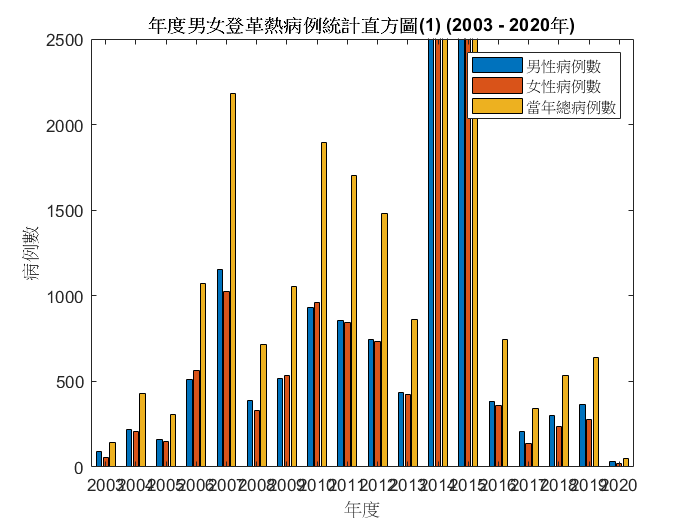

maleCasesCount = sum(gather((maleCases.year==[2003:2020]).*maleCases.cases));
femaleCasesCount = sum(gather((femaleCases.year==[2003:2020]).*femaleCases.cases));
totalCasesCount = maleCasesCount + femaleCasesCount;

bar([2003:2020],[maleCasesCount ;femaleCasesCount; totalCasesCount], 'grouped')
set(gca, 'XTick', 2003:2020)
ylim([0 2500]);
title('年度男女登革熱病例統計直方圖(1) (2003 - 2020年)')
xlabel('年度')
ylabel('病例數')
legend('男性病例數', '女性病例數','當年總病例數')

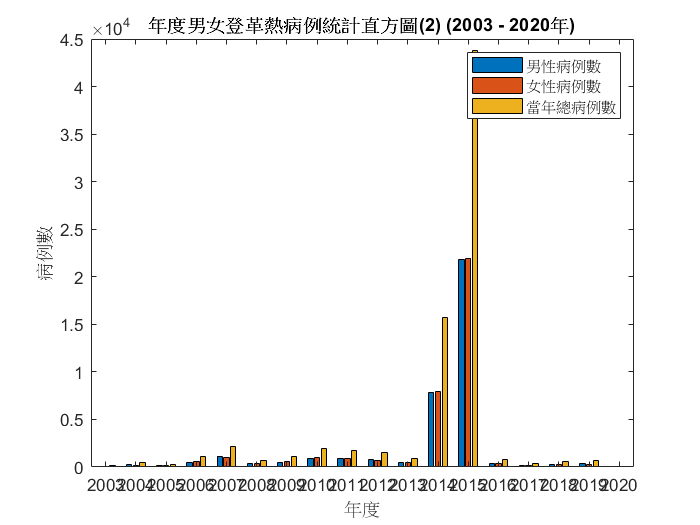

% 年度男女登革熱病例統計直方圖(2) (2003 - 2020年)
bar([2003:2020],[maleCasesCount ;femaleCasesCount; totalCasesCount], 'grouped')
set(gca, 'XTick', 2003:2020)
title('年度男女登革熱病例統計直方圖(2) (2003 - 2020年)')
xlabel('年度')
ylabel('病例數')
legend('男性病例數', '女性病例數','當年總病例數')

% 各縣市病例數圓餅圖(2003-2020年)
cityCategories = categories(categorical(gather(dengueTall.city)));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.025 sec
Evaluation completed in 0.026 sec


cityCategories = reshape(cityCategories,1,22);
cityTall = gather(dengueTall{:,'city'});

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.029 sec
Evaluation completed in 0.031 sec


cityCasesCount = [];
for i = 1:length(cityCategories)
    cityCasesTable = gather(dengueTall(find(ismember(cityTall,cityCategories{i})),:));
    cityCasesCount = [cityCasesCount sum(cityCasesTable.cases)];
end

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.048 sec
- Pass 2 of 2: Completed in 0.058 sec
Evaluation completed in 0.21 sec
Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.044 sec
- Pass 2 of 2: Completed in 0.083 sec
Evaluation completed in 0.24 sec
Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.046 sec
- Pass 2 of 2: Completed in 0.052 sec
Evaluation completed in 0.19 sec
Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.044 sec
- Pass 2 of 2: Completed in 0.057 sec
Evaluation completed in 0.21 sec
Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.042 sec
- Pass 2 of 2: Completed in 0.051 sec
Evaluation completed in 0.19 sec
Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.042 sec
- Pass 2 of 2: Completed in 0.054 sec
Evaluation completed in 0

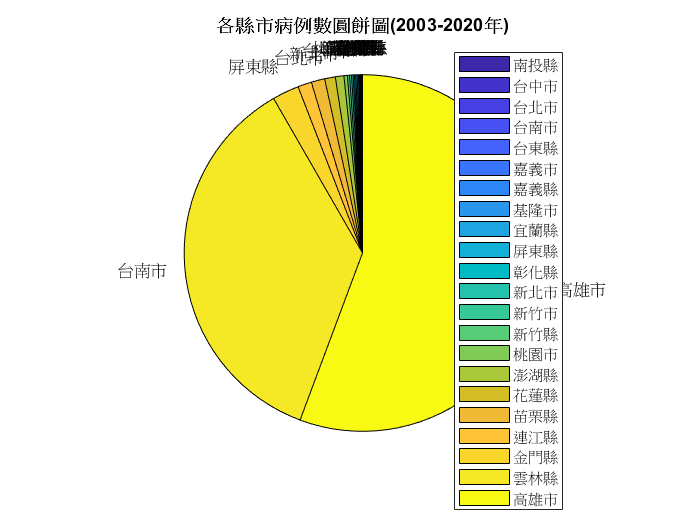

[sortedCityCount,sortedIndex] = sort(cityCasesCount);
sortedCityCategories = cityCategories(sortedIndex);
pie(sortedCityCount,sortedCityCategories)
title('各縣市病例數圓餅圖(2003-2020年)')
legend(cityCategories)


% 各縣市病例統計排名水平直方圖(2003 - 2020年)
cityBarh = barh(sortedCityCount)

cityBarh =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22]
        YData: [2 10 45 45 50 55 57 87 89 89 90 106 134 142 227 571 710 901 925 1786 26517 41023]

  Show all properties


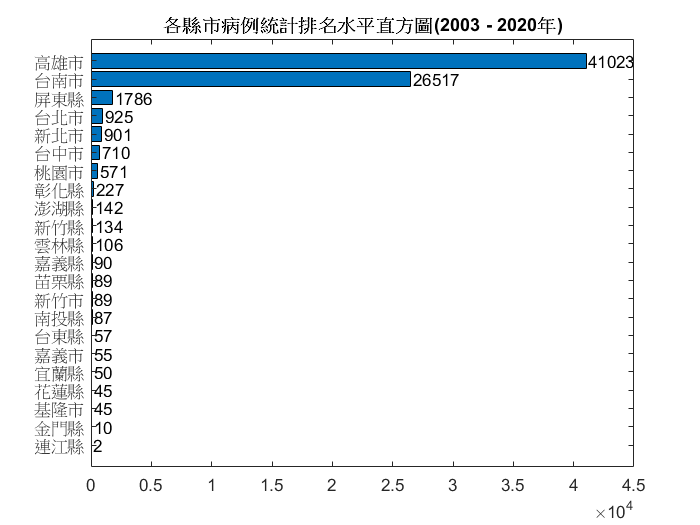

xtips1 = cityBarh(1).YEndPoints + 200;
ytips1 = cityBarh(1).XEndPoints;
labels1 = string(cityBarh(1).YData);
text(xtips1,ytips1,labels1,'VerticalAlignment','middle')
set(gca, 'YTick', 1:22)
set(gca, 'YTickLabel', sortedCityCategories)
title('各縣市病例統計排名水平直方圖(2003 - 2020年)')

ageCategories = categories(categorical(gather(dengueTall.age)));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.027 sec
Evaluation completed in 0.029 sec


ageTall = gather(dengueTall{:,'age'});

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.039 sec
Evaluation completed in 0.042 sec


% 年齡層排序
ageNum = [];
for i = 1:length(ageCategories)
    ageStr = split(ageCategories{i},["-","+"]);
    ageNum = [ageNum str2num(ageStr{1})];
end
ageCasesCount = [];
femaleAgeCaseCount = [];
maleAgeCaseCount = [];
% 各年齡年齡病例數統計
for i = 1:length(ageCategories)
    ageCasesTable = gather(dengueTall(find(ismember(ageTall,ageCategories{i})),:));
    ageCasesCount = [ageCasesCount sum(ageCasesTable.cases)];
    femaleAgeCase = ageCasesTable(find(ismember(ageCasesTable.gender,'F')),:);
    maleAgeCase = ageCasesTable(find(ismember(ageCasesTable.gender,'M')),:);
    femaleAgeCaseCount = [femaleAgeCaseCount sum(femaleAgeCase.cases)];
    maleAgeCaseCount = [maleAgeCaseCount sum(maleAgeCase.cases)];
end

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.043 sec
- Pass 2 of 2: Completed in 0.055 sec
Evaluation completed in 0.19 sec
Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.045 sec
- Pass 2 of 2: Completed in 0.053 sec
Evaluation completed in 0.28 sec
Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.052 sec
- Pass 2 of 2: Completed in 0.06 sec
Evaluation completed in 0.22 sec
Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.043 sec
- Pass 2 of 2: Completed in 0.052 sec
Evaluation completed in 0.19 sec
Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.046 sec
- Pass 2 of 2: Completed in 0.052 sec
Evaluation completed in 0.2 sec
Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.045 sec
- Pass 2 of 2: Completed in 0.057 sec
Evaluation completed in 0.2

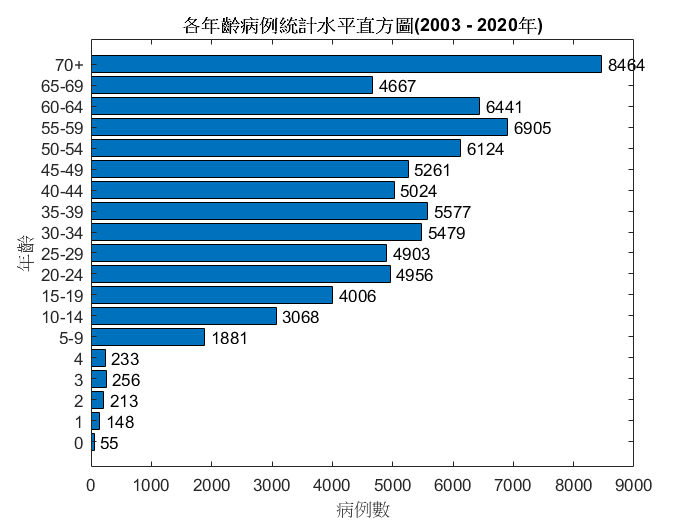

[d,sortedAgeIndex] = sort(ageNum);
ageBarh = barh(ageCasesCount(sortedAgeIndex));

% 各年齡病例統計水平直方圖(2003 - 2020年)
xtips1 = ageBarh(1).YEndPoints + 100;
ytips1 = ageBarh(1).XEndPoints;
labels1 = string(ageBarh(1).YData);
text(xtips1,ytips1,labels1,'VerticalAlignment','middle')
set(gca, 'YTick', 1:19)
set(gca, 'YTickLabel', ageCategories(sortedAgeIndex))
xlabel('病例數')
ylabel('年齡')
title('各年齡病例統計水平直方圖(2003 - 2020年)')


% 各年齡層男女病例統計圖(2003 - 2020年)
totalHist = histogram('Categories',ageCategories(sortedAgeIndex),'FaceColor','#EDB120','BinCounts',ageCasesCount(sortedAgeIndex))

totalHist =   Histogram with properties:

              Data: [0×0 categorical]
            Values: [55 148 213 256 233 1881 3068 4006 4956 4903 5479 5577 5024 5261 6124 6905 6441 4667 8464]
    NumDisplayBins: 19
        Categories: {'0'  '1'  '2'  '3'  '4'  '5-9'  '10-14'  '15-19'  '20-24'  '25-29'  '30-34'  '35-39'  '40-44'  '45-49'  '50-54'  '55-59'  '60-64'  '65-69'  '70+'}
      DisplayOrder: 'manual'
     Normalization: 'count'
      DisplayStyle: 'bar'
         FaceColor: [0.9294 0.6941 0.1255]
         EdgeColor: [0 0 0]

  Show all properties


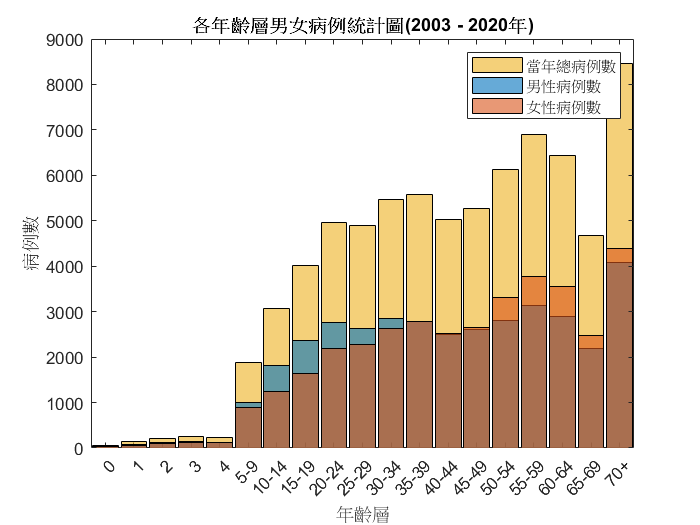

hold on
histogram('Categories',ageCategories(sortedAgeIndex),'FaceColor','#0072BD','BinCounts',maleAgeCaseCount(sortedAgeIndex))
histogram('Categories',ageCategories(sortedAgeIndex),'FaceColor','#D95319','BinCounts',femaleAgeCaseCount(sortedAgeIndex))
hold off
legend('當年總病例數','男性病例數', '女性病例數')
title('各年齡層男女病例統計圖(2003 - 2020年)')
xlabel('年齡層')
ylabel('病例數')